clc
clear
%作者；暴富
%时间：2024-06-25
%项目：example2.3公式法


%并行池的开和关
%parpool%开
%delete(gcp)%关

%%初始化
T = 0.01;
t = 0:T:15;
N = length(t);
X = zeros(6,9,N);%agent初始化,两个图

lineStyles = linspecer(6); % 指定线型颜色,6个状态

%agengt状态初始化
X(1,:,1) = 1;
X(2,:,1) = -1;
X(3,:,1) = 3;
X(4,:,1) = -3;
X(5,:,1) = 5;
X(6,:,1) = -5;


%%图A的邻接矩阵
A(:,:,1) = [ 0  0   1  0  0  0;...
            1  0   0  0  0  1;...
            1  1   0  0  0  0;...
            0  1   0  0  0  0;...
            0  0   1  0  0  0;...
            0  0   0  1  1  0];
A(:,:,2) = [ 0  1   1  0  0  0;...
           1  0   1  1  0  1;...
           1  1   0  0  1  0;...
           0  1   0  0  0  1;...
           0  0   1  0  0  1;...
           0  1   0  1  1  0];

%% 图c的特征值
A(:,:,3) = [ 0  1   1  1  1  1;...
           1  0   1  1  1  1;...
           1  1   0  1  1  1;...
           1  1   1  0  1  1;...
           1  1   1  1  0  1;...
           1  1   1  1  1  0];
     
   
   
%% 图d的特征值
A(:,:,4) = [ 0  0   0  0  0  0;...
           1  0   0  0  0  0;...
           1  0   0  0  0  0;...
           0  1   0  0  0  0;...
           0  0   1  0  0  0;...
           0  0   1  0  0  0];

         
%% 图e的特征值
A(:,:,5) = [ 0  1   1  1  1  1;...
           1  0   0  0  0  0;...
           1  0   0  0  0  0;...
           1  0   0  0  0  0;...
           1  0   0  0  0  0;...
           1  0   0  0  0  0];
       

   
%% 图f的特征值
A(:,:,6) = [ 0  0   0  0  0  0;...
           1  0   0  0  0  0;...
           1  0   0  0  0  0;...
           1  0   0  0  0  0;...
           1  0   0  0  0  0;...
           1  0   0  0  0  0];
   

%% 图g的特征值
A(:,:,7) = [ 0  1   0  0  0  1;...
           1  0   1  0  0  0;...
           0  1   0  1  0  0;...
           0  0   1  0  1  0;...
           0  0   0  1  0  1;...
           1  0   0  0  1  0];
   
%% 图h的特征值
A(:,:,8) = [ 0  0   0  0  0  1;...
           1  0   0  0  0  0;...
           0  1   0  0  0  0;...
           0  0   1  0  0  0;...
           0  0   0  1  0  0;...
           0  0   0  0  1  0];
   
%% 图i的特征值
A(:,:,9) = [ 0  1   0  0  0  0;...
           1  0   1  0  0  0;...
           0  1   0  1  0  0;...
           0  0   1  0  1  0;...
           0  0   0  1  0  1;...
           0  0   0  0  1  0];
  

%%迭代过程
%%n代表9个图，是x的列，k表示切片，是每个agent迭代的state，ii和jj表示单个agent的state，是x的行
for n =1:9
    for k = 2:N
        for ii = 1:6
            sum_term = 0;
            for jj = 1:6
                sum_term = sum_term + A(ii,jj,n)*(X(jj,n,k-1)-X(ii,n,k-1));
            end
            X(ii,n,k) = T*sum_term + X(ii,n,k-1);
        end
    end
end

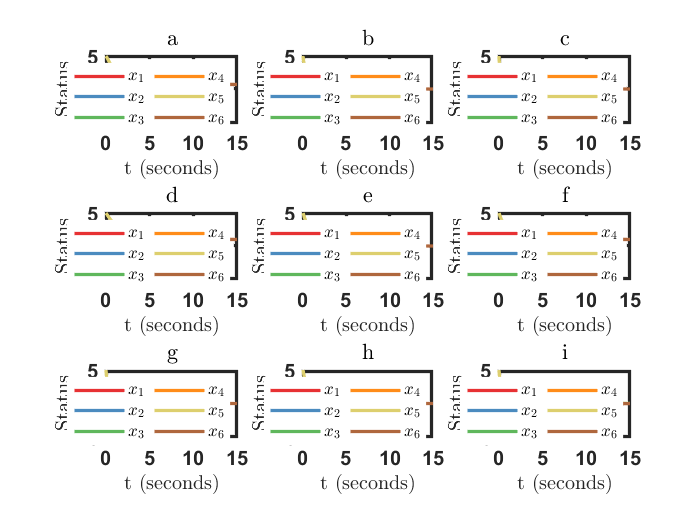

%% 绘制结果
hf = figure;  %新建 图形控制句柄
hf.Color= [1 1 1]; % 控制图形的整体颜色。（scope中被默认为灰黑色，此处修改为白色）

subplot(3,3,1)
%线形设置
plot(t,reshape(X(1,1,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,1,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,1,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,1,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,1,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,1,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','a')

subplot(3,3,2)  % 图b
% 线型设置
plot(t,reshape(X(1,2,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,2,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,2,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,2,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,2,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,2,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','b')

subplot(3,3,3)  % 图c
% 线型设置
plot(t,reshape(X(1,3,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,3,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,3,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,3,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,3,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,3,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','c')


subplot(3,3,4)  % 图d
% 线型设置
plot(t,reshape(X(1,4,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,4,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,4,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,4,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,4,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,4,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','d')



subplot(3,3,5)  % 图e
% 线型设置
plot(t,reshape(X(1,5,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,5,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,5,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,5,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,5,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,5,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','e')


subplot(3,3,6)  % 图f
% 线型设置
plot(t,reshape(X(1,6,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,6,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,6,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,6,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,6,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,6,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','f')


subplot(3,3,7)  % 图g
% 线型设置
plot(t,reshape(X(1,7,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,7,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,7,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,7,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,7,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,7,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','g')


subplot(3,3,8)  % 图h
% 线型设置
plot(t,reshape(X(1,8,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,8,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,8,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,8,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,8,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,8,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','h')


subplot(3,3,9)  % 图i
% 线型设置
plot(t,reshape(X(1,9,:),1,N),'Color',lineStyles(1,:),'linestyle','-','linewidth',2); 
hold on
plot(t,reshape(X(2,9,:),1,N),'Color',lineStyles(2,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(3,9,:),1,N),'Color',lineStyles(3,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(4,9,:),1,N),'Color',lineStyles(4,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(5,9,:),1,N),'Color',lineStyles(5,:),'linestyle','-','linewidth',2); 
plot(t,reshape(X(6,9,:),1,N),'Color',lineStyles(6,:),'linestyle','-','linewidth',2); 
FigPorperty('t (seconds)','Status','i')